# Batch Processing

In this livescript, we will cover ways to process multiple datasets. So far, we have only concentrated on a single dataset. How about the others? It would be cumbersome to repeat lines of code to preprocess multiple files or change the file path manually for each time (something I am guilty of when I first started learning how to code). This is why looping is very important! We can loop through multiple datasets and preprocess them at every iteration. 

## For Loops

In computer science, a **for loop** is a control flow statement for specifying iteration. It functions by running a section of code repeatedly until a certain condition has been satisfied. For MATLAB, here is the official [documentation](https://www.mathworks.com/help/matlab/ref/for.html). Let's look at a basic for loop written in MATLAB: 

%Example for loop: 
for i = 5:9
    i 
end


i = 5

i = 6

i = 7

i = 8

i = 9

Notice the **end** of the for loop. If you forget to write end, you will get an error. Remember:** For every *****for*****, you need an end! **This applies to any if/else or while statements. Also, the **i** variable changes in value in each iteration, a total of 5 times. This is because of array (**1:5**). Change the numbers and see what i is equal in each iteration. This array can be something random. For instance if you put 5:9, then i would output 5, 6, 7, 8 ,and 9, or if you put [7,4,3,2,7], i would output 7, 4, 3, 2, and 7. There is also no requirement that you have to use the **variable i**. You can use any letter or word. Decrementing values is also possible. We will use a different variable and a decrementing array: 




for index_something = array_1

array_1 =      1     4     6     7     8


    index_something

array_2 =      1     3    54     6     2


end
for i = 1:length(array_1)
    array_1(i)
    array_2(i)

index_something = 1

index_something = 4

index_something = 6

index_something = 7

index_something = 8

end

That seems pretty simple. But we can complicate things with a nested for loop; that is, we can have a for loop inside of a for loop (for loop inception). Nested for loops can be useful when filling out a matrix full of values, iterating over rows and columns. As you will see later, we can use nested for loops to iterate over subjects and their multiple datasets. 

%Initializing an matrix with 20 rows and 14 columns

ans = 1

ans = 1

ans = 4

ans = 3

ans = 6

ans = 54

ans = 7

ans = 6

ans = 8

ans = 2

mat = zeros(20,14);

%We will iterate over rows: 
for i = 1:size(mat,1)
    %Iterating over columns
    for j = 1:size(mat,2)
        mat(i,j) = i + j;
    end
end

%Displaying resulting matrix
mat

We can skip certain iterations with **continue**. For instance, we can skip certain subjects if we need to process them differently. Let's look at a one example

%Skipping any values divisible by 3; we use the modulo function to do this,
%so look at the description by typing help mod in the command window
for i = 1:17

mat =      2     3     4     5     6     7     8     9    10    11    12    13    14    15
     3     4     5     6     7     8     9    10    11    12    13    14    15    16
     4     5     6     7     8     9    10    11    12    13    14    15    16    17
     5     6     7     8     9    10    11    12    13    14    15    16    17    18
     6     7     8     9    10    11    12    13    14    15    16    17    18    19
     7     8     9    10    11    12    13    14    15    16    17    18    19    20
     8     9    10    11    12    13    14    15    16    17    18    19    20    21
     9    10    11    12    13    14    15    16    17    18    19    20    21    22
    10    11    12    13    14    15    16    17    18    19    20    21    22    23
    11    12    13    14    15    16    17    18    19    20    21    22    23    24


    %Checking if value is divisible by 3
    % if it is, we skip with continue
    if mod(i,3) == 0
        continue
    end
    %displaying i
    i
end

i = 1

i = 2

i = 4

i = 5

i = 7

i = 8

i = 10

i = 11

i = 13

i = 14

i = 16

i = 17

For loops can be used a lot in different scenarios. For instance, the EEGLAB** topoplot** function plots a typical topographical EEG scalp map as shown below:

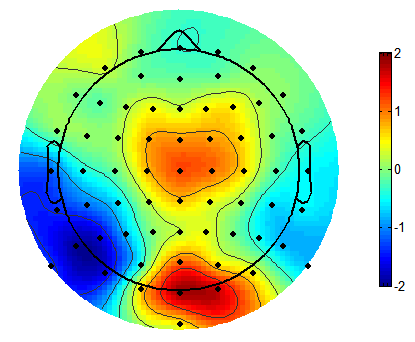

The values indicated by the color can be mean amplitude, p-values, t-scores, power spectra density, or mean band power. This function **topoplot **takes in a n x 1 vector storing these values where n indicates the number of channels and channel locations associated with these values. Let's say we want to get mean alpha power (8-13 Hz) for 5 subjects. This is easy to calculate as we can use the EEGLAB** spectopo** function to calculate power spectral density across many frequencies. With the output of the **spectopo **function, we get a spectra matrix of size n x mfreqs, where n indicates the number of channels and mfreqs indicates the number of frequences (1 to 50 Hz). We can calculate the mean alpha band power between 8 Hz and 13 Hz from this spectra matrix for each of the 5 subjects, resulting in a n x 1 vector we can use in the topoplot for each subject. We can iterate through each subject, use spectopo, average alpha power, and store the average alpha power vector in an empy array with size n x 5. Then we can calculate the mean across all subjects and plot it with topoplot. We will write this code in a later tutorial covering frequency analysis. 

We can also use for loops to batch preprocess datasets. We can for loop through subject EEG data, preprocess them in every iteration, and save the clean dataset. This is what we will cover in this tutorial. The tricky part in creating these batch preprocessing loops is figuring out how to load in the datasets you have to preproces. I will show you three ways, but each way have their own weaknesses. There are probably other ways, but these are some that I have used in the past and currently.

WILL FINISH AND ADD MORE TUTORIALS (CURRENT DATE: 3/14/2023)